2. Concepeti o reprezentare grafica intuitiva pentru formula trapezelor si formula repetata a lui Simpson (facultativ).

### Regula lui Simpson

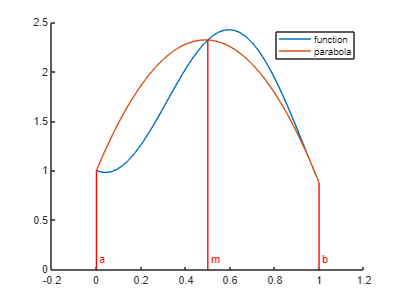

f = @(x) 2-sin(x)-cos(5*x);

a = 0; b=1;
gx = linspace(a,b); gy = f(gx);

m = (a+b)/2;
par = polyfit([a,m,b],[f(a),f(m),f(b)],2);


clf; hold on;
plot(gx, gy);
plot(gx, polyval(par, gx))
plot([a,a],[0, f(a)], 'color','r')
plot([m,m],[0, f(m)],'color','r')
plot([b,b],[0, f(b)],'color','r')
text(a, 0.1, " a",'color','r'); 
text(m, 0.1, " m",'color','r'); 
text(b, 0.1, " b",'color','r');
xlim([a-0.2,b+0.2])
legend("function", "parabola")
hold off;


$$\int_a^bf(x)dx \approx \frac{b-a}{6}\left( 
    f(a)+4f(\frac{a+b}{2})+f(b)
 \right)$$


### Regula trapezului

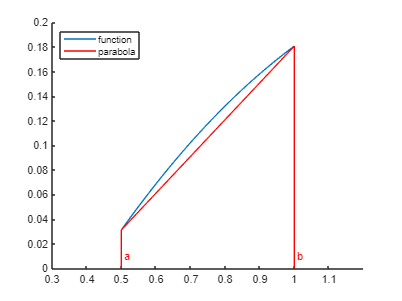

f = @(x) tanh(x)/2-0.2;

a = 0.5; b=1;
gx = linspace(a,b); gy = f(gx);

clf; hold on;
plot(gx, gy);
plot([a,b],[f(a),f(b)],'color','r')
plot([a,a],[0, f(a)], 'color','r')
plot([b,b],[0, f(b)],'color','r')
text(a, 0.01, " a",'color','r');  
text(b, 0.01, " b",'color','r');
xlim([a-0.2,b+0.2])
legend("function", "parabola","Location","northwest")
hold off;


$$\int_a^bf(x)dx\approx \frac{b-a}{2}(f(a)+f(b))$$
